## 1)

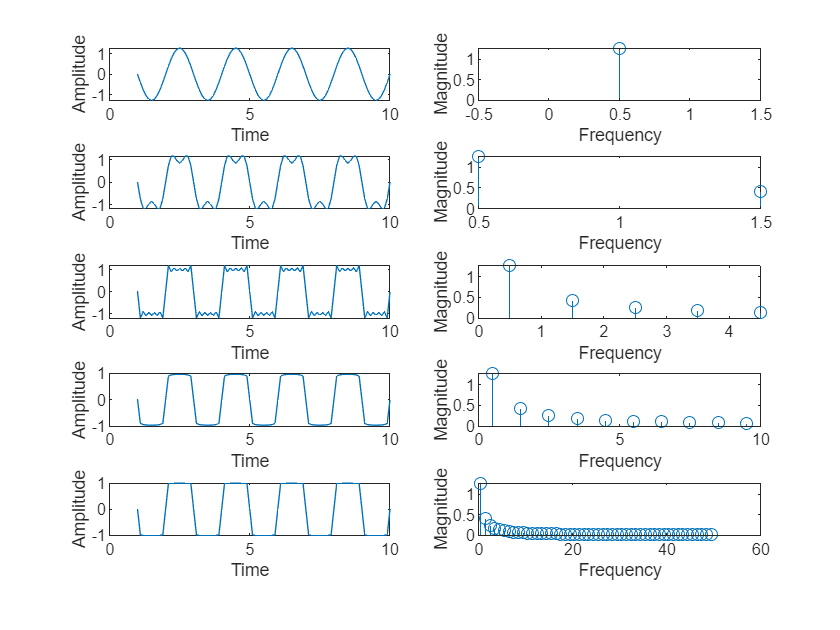

t=1:0.1:10;

A=1;
T=2;
w=(2*pi)/T;
figure(1)
subplot(5,2,1)
[~,coef,freq] = costam(A,t,w,1);
ylabel('Amplitude')
xlabel('Time')
subplot(5,2,2)
stem(freq,coef);
ylabel('Magnitude')
xlabel('Frequency')
subplot(5,2,3)
[~,coef,freq] = costam(A,t,w,3);
ylabel('Amplitude')
xlabel('Time')
subplot(5,2,4)
stem(freq,coef);
ylabel('Magnitude')
xlabel('Frequency')
subplot(5,2,5)
[~,coef,freq] = costam(A,t,w,10);
ylabel('Amplitude')
xlabel('Time')
subplot(5,2,6)
stem(freq,coef);
ylabel('Magnitude')
xlabel('Frequency')
subplot(5,2,7)
[~,coef,freq] = costam(A,t,w,20);
ylabel('Amplitude')
xlabel('Time')
subplot(5,2,8)
stem(freq,coef);
ylabel('Magnitude')
xlabel('Frequency')
subplot(5,2,9)
[y,coef,freq] = costam(A,t,w,100);
ylabel('Amplitude')
xlabel('Time')
subplot(5,2,10)
stem(freq,coef);
ylabel('Magnitude')
xlabel('Frequency')

Above we observe that increacing the number of sin waves allows us to more accurately represent a square function 

## 2)

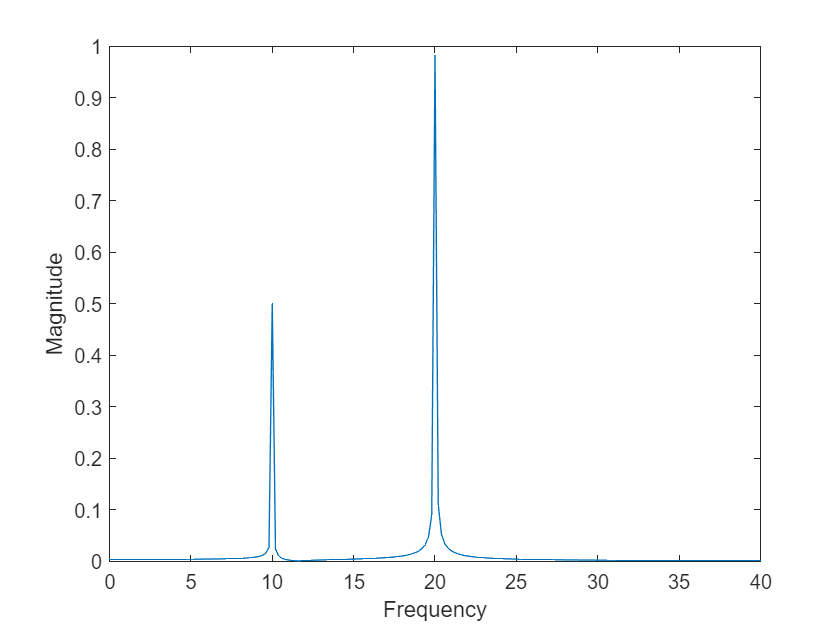

clear;
N=1001;
fs=200;
dt=1/fs;
df=fs/(N-1);

n=0;
f=df*(0:N-1);
t=dt*(0:N-1);
x = cos(2*pi*10*t)+2*cos(2*pi*20*t);

y=fft(x);
m=abs(y)/N;
p=rad2deg(unwrap(angle(y)));
figure(2);
plot(f,m);
ylabel('Magnitude')
xlabel('Frequency')
xlim([0 40]);

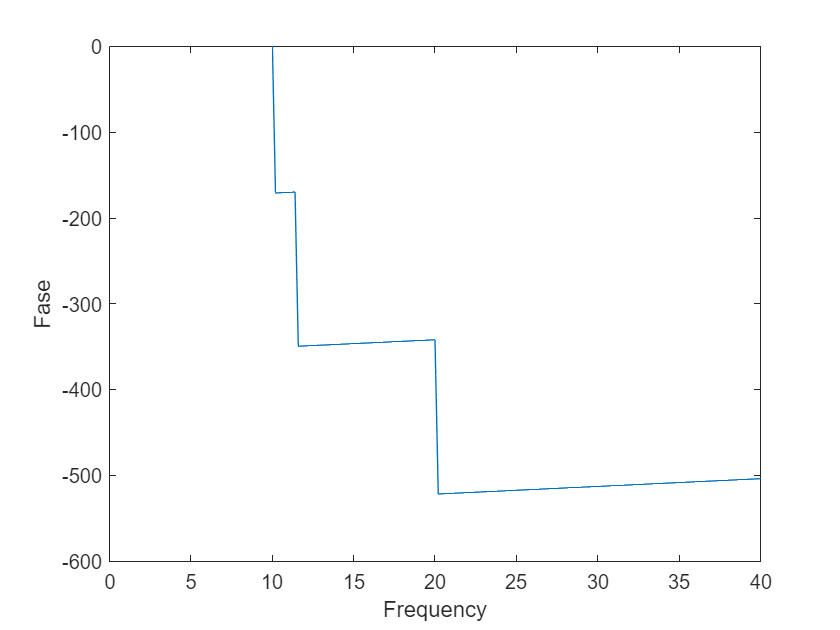

figure(3)
plot(f,p);
ylabel('Fase')
xlabel('Frequency')
xlim([0 40]);
ylim([-600 0])

## 3)

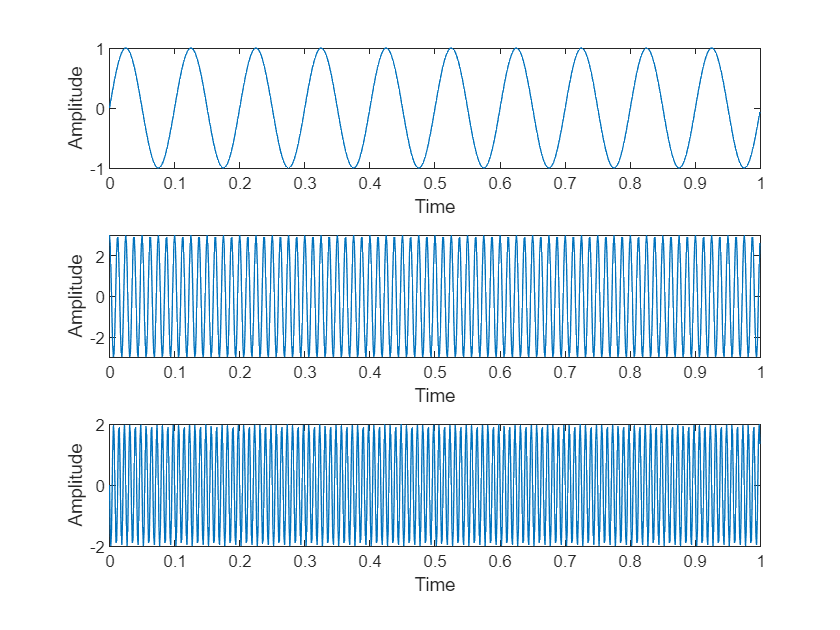

clear
N=1000;  %resolution is 1000 samples per second
fs=1000;
t=0:1/fs:(N/fs)-(1/fs);
x1=sin(2*pi*t*10);
x2=3*sin(2*pi*t*80+pi/2);
x3=2*sin(2*pi*t*120+pi);
figure(4)
subplot(3,1,1)
plot(t,x1)
ylabel('Amplitude')
xlabel('Time')
subplot(3,1,2)
plot(t,x2)
ylabel('Amplitude')
xlabel('Time')
subplot(3,1,3)
plot(t,x3)
ylabel('Amplitude')
xlabel('Time')

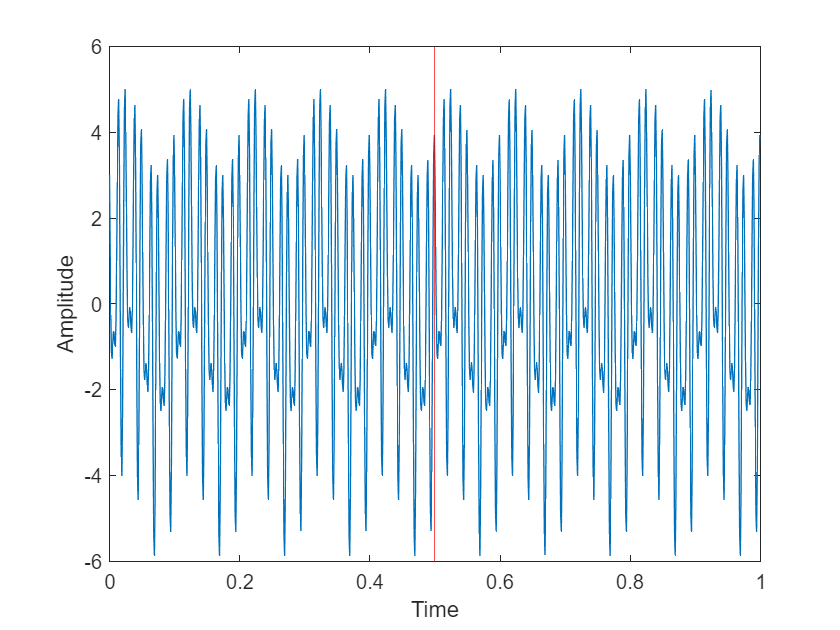


x4=x1+x2+x3;
figure(5)
plot(t,x4);
hold on;
figure(5)
xline(0.5,'r');
ylabel('Amplitude')
xlabel('Time')

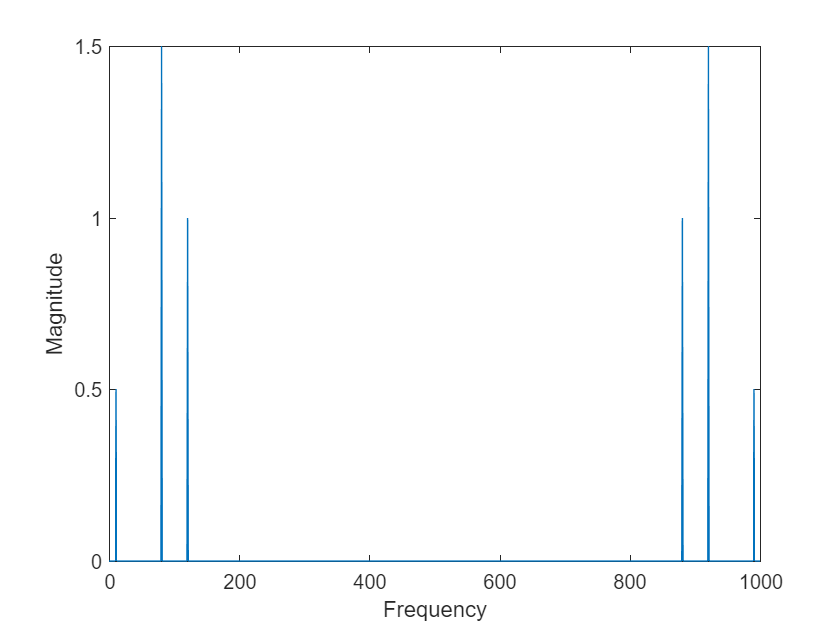

figure(6)
y=fft(x4);
m=abs(y)/N;
p=rad2deg(unwrap(angle(y)));
df=fs/(N);
f=df*(0:N-1);
plot(f,m);
ylabel('Magnitude')
xlabel('Frequency')
xlim([0 1000]);

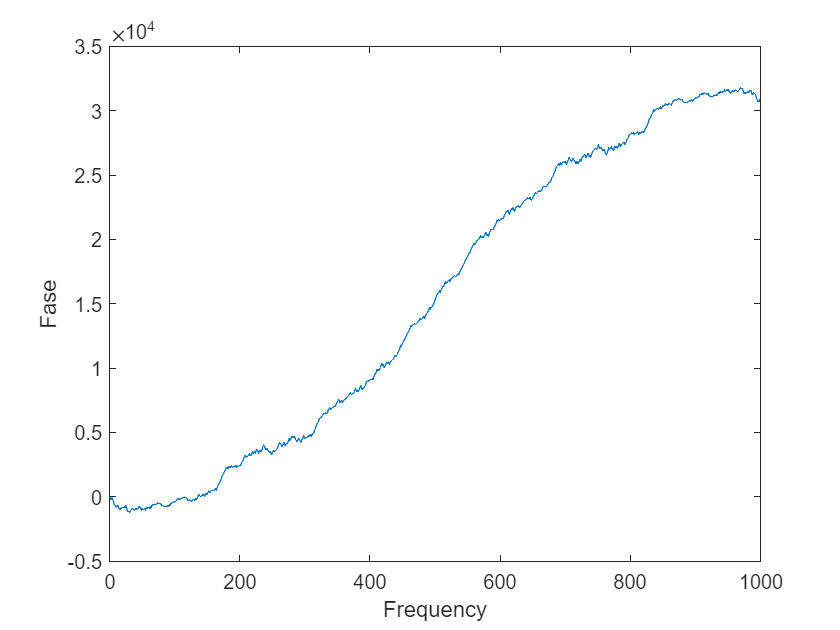


figure(7)
plot(f,p);
ylabel('Fase')
xlabel('Frequency')
xlim([0 1000]);

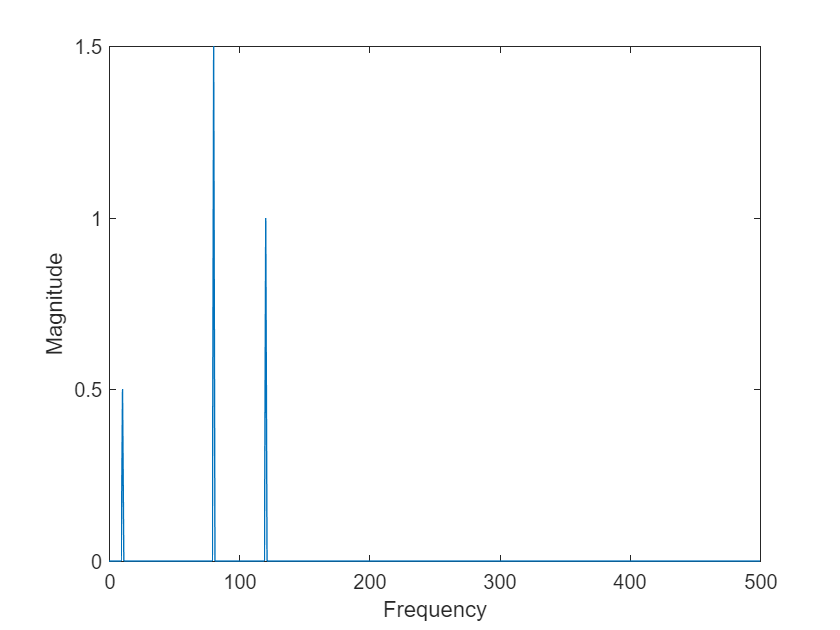


Fn = fs/2;               % Nyquist Frequency
figure(8)
plot(f,m);
ylabel('Magnitude')
xlabel('Frequency')
xlim([0 500]);

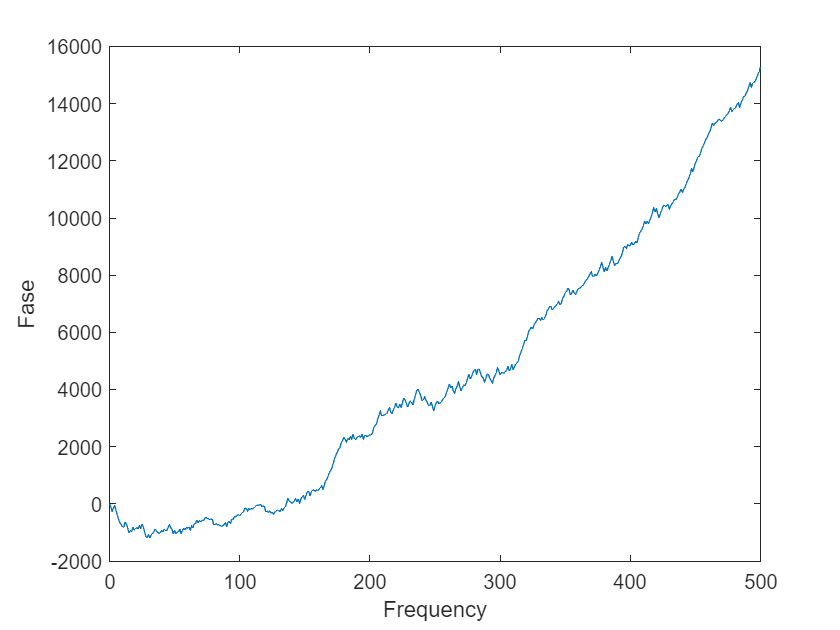

figure(9)
plot(f,p);
ylabel('Fase')
xlabel('Frequency')
xlim([0 500]);

## 4)

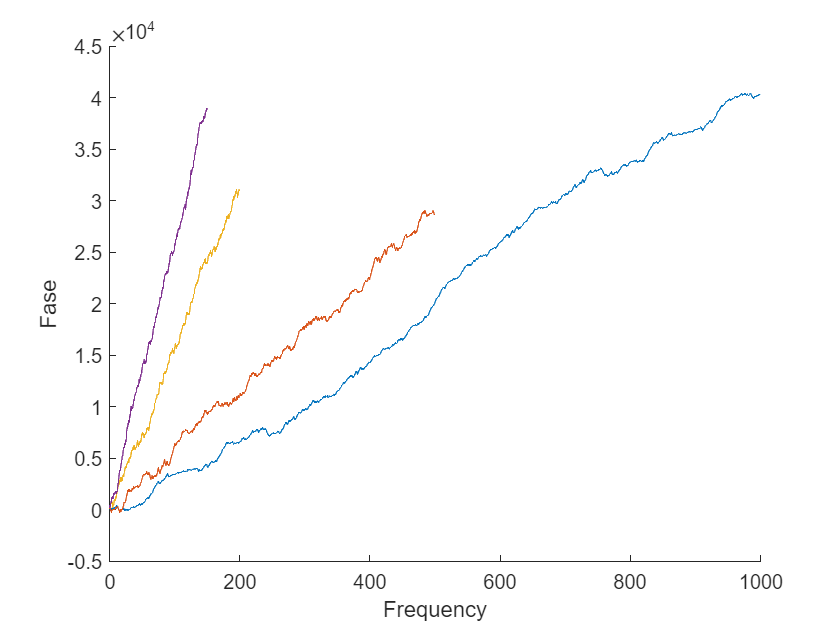

clear
i=0;
N=1000;
for fs=[1000 500 200 150]
    i=i+1;
    t(i,:)=0:1/fs:(N/fs)-(1/fs);
    x(i,:)=sin(2*pi*t(i,:)*120);
    y(i,:)=fft(x(i,:));
    m(i,:)=abs(y(i,:))/N;
    p(i,:)=rad2deg(unwrap(angle(y(i,:))));
    df(i,:)=fs/(N);
    f(i,:)=df(i,:)*(0:N-1);
    figure(10)
hold on
    plot(f(i,:),p(i,:));
    ylabel('Fase')
xlabel('Frequency')
    figure(11)
hold on
plot(f(i,:),m(i,:));
end

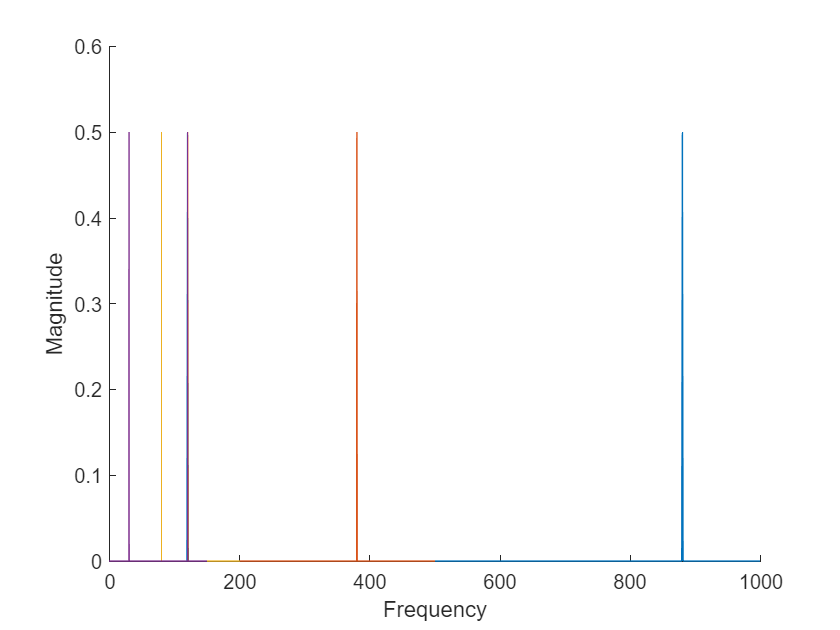


ylabel('Magnitude')
xlabel('Frequency')
hold off

## 5)

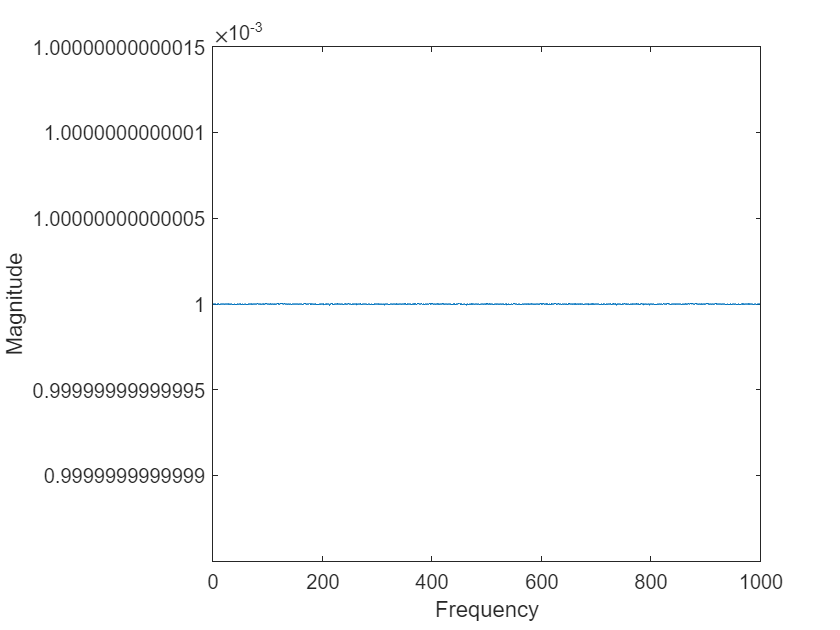

clear
N=1000;
fs=1000;
t=0:1/fs:(N/fs)-(1/fs);
x=zeros(1,1000);
x(200)=1;
x=fft(x);
m=abs(x)/N;
p=rad2deg(unwrap(angle(x)));
df=fs/(N);
f=df*(0:N-1);
plot(f,m);
ylabel('Magnitude')
xlabel('Frequency')

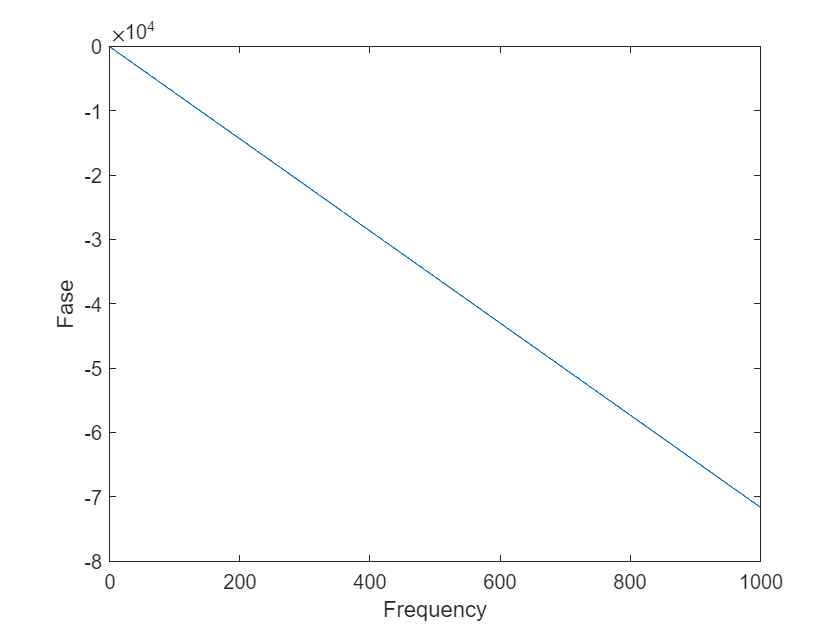

plot(f,p);
 ylabel('Fase')
xlabel('Frequency')

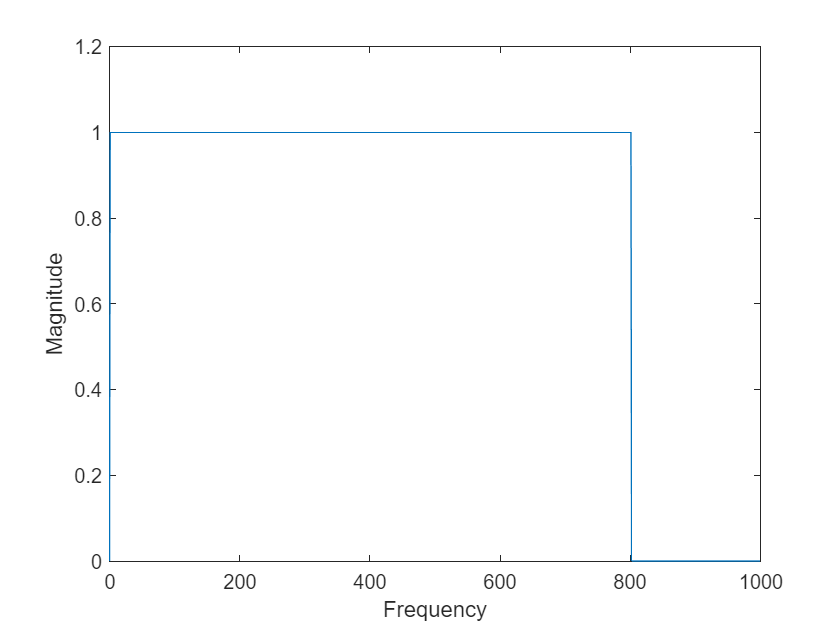


x1=zeros(1,1000);
x1(1,200:end)=ones(1,801);
x1=fft(x1);
x1=fft(x1);
m=abs(x1)/N;
p=rad2deg(unwrap(angle(x1)));
plot(f,m);
ylabel('Magnitude')
xlabel('Frequency')

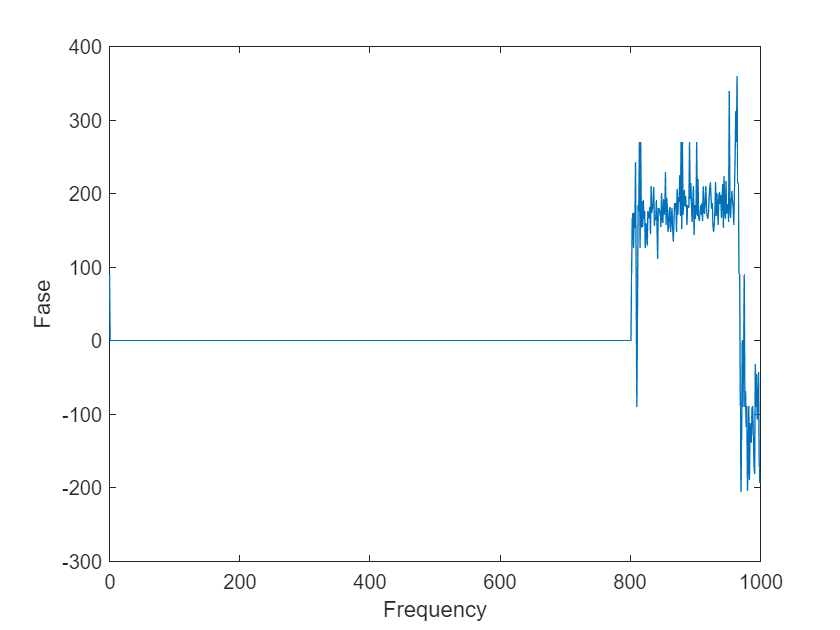

plot(f,p);
 ylabel('Fase')
xlabel('Frequency')

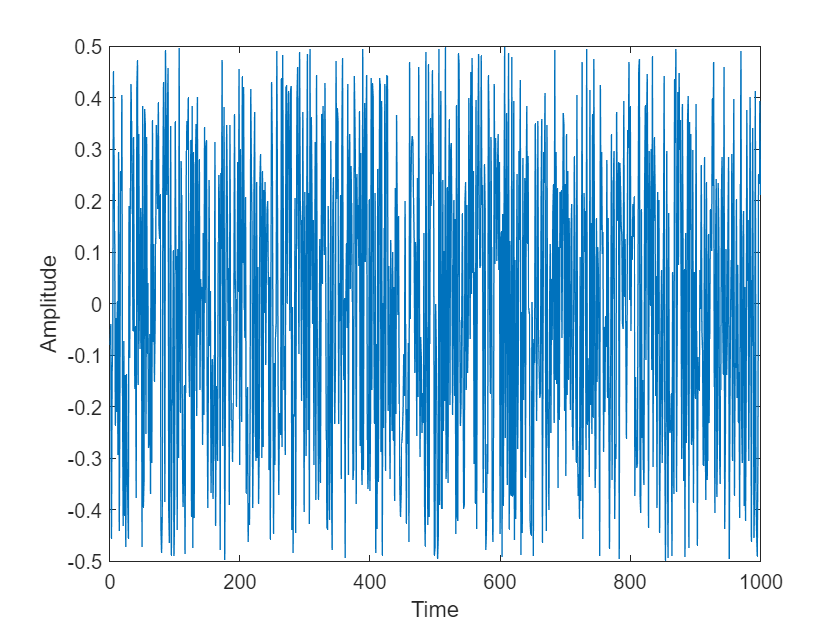

x2=0.5-rand(1,1000);
plot(x2)
ylabel('Amplitude')
xlabel('Time')

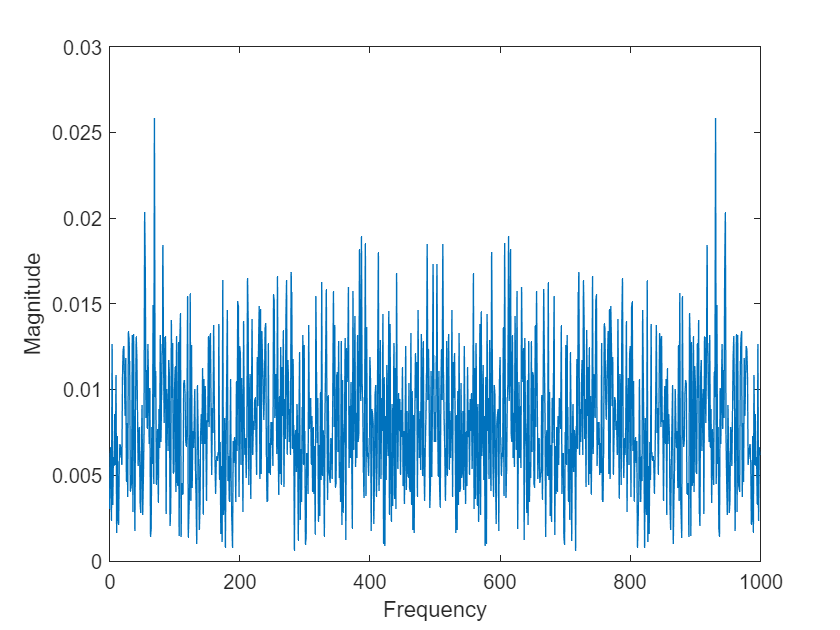

x2=fft(x2);
m=abs(x2)/N;
p=rad2deg(unwrap(angle(x2)));
plot(f,m);
ylabel('Magnitude')
xlabel('Frequency')

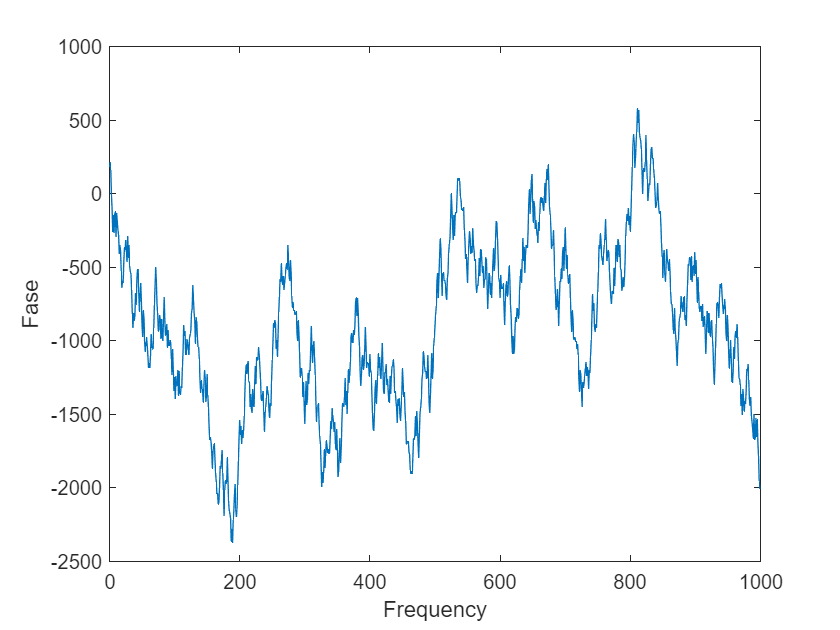

plot(f,p);
 ylabel('Fase')
xlabel('Frequency')

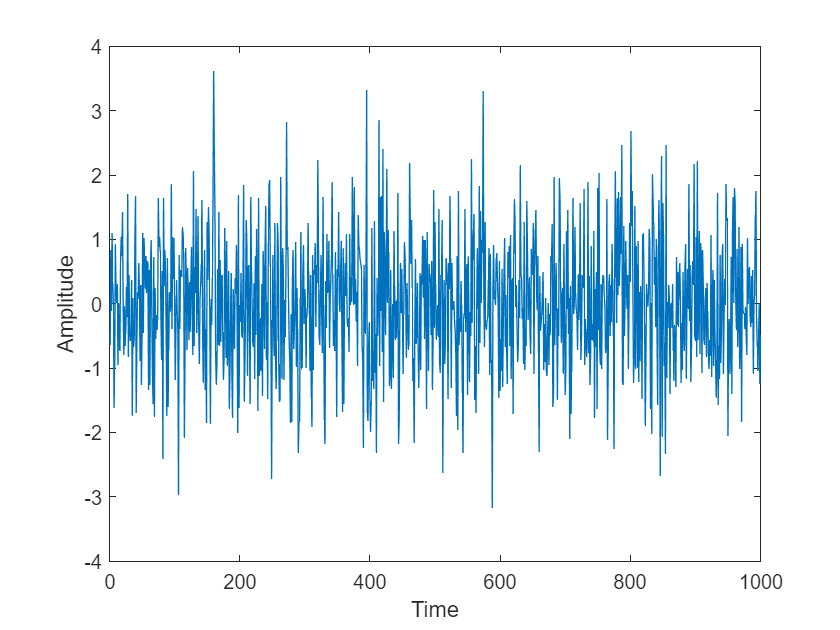

x3=randn(1,1000);
plot(x3)
ylabel('Amplitude')
xlabel('Time')

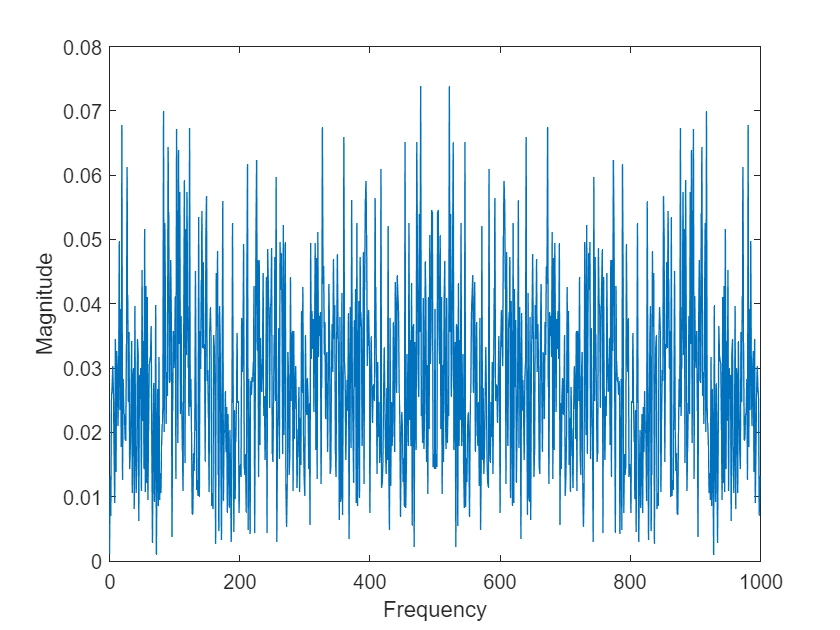

x3=fft(x3);
m=abs(x3)/N;
p=rad2deg(unwrap(angle(x3)));
plot(f,m);
ylabel('Magnitude')
xlabel('Frequency')

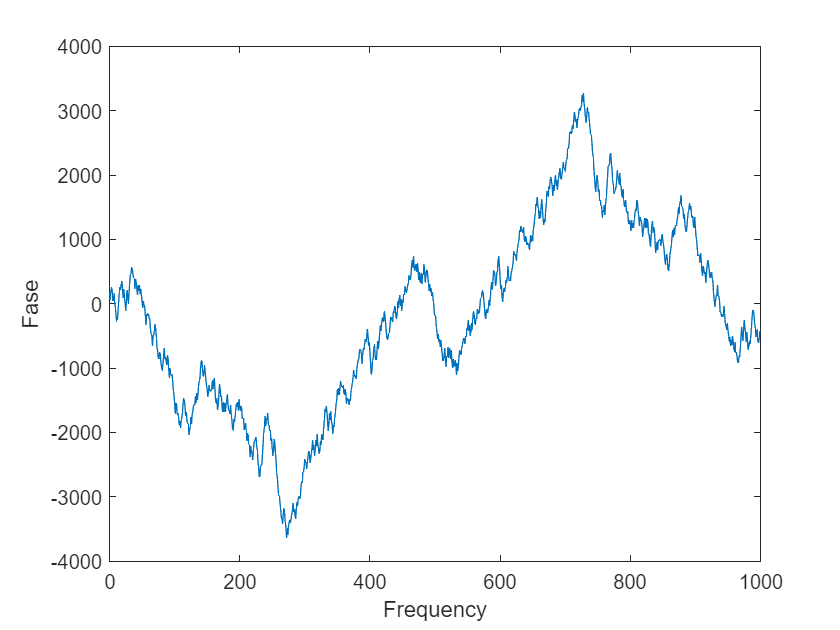

plot(f,p);
 ylabel('Fase')
xlabel('Frequency')

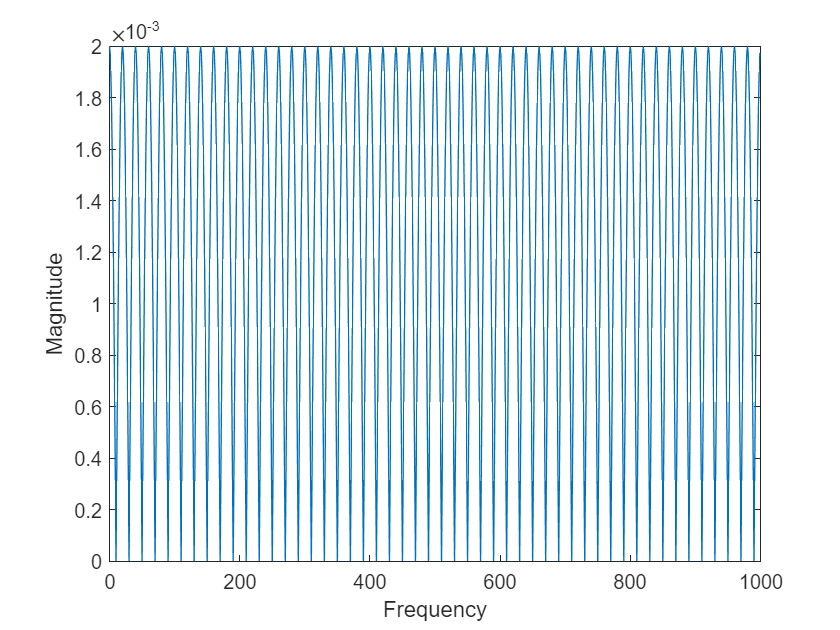

x4=zeros(1,1000);
x4(200)=1;
x4(250)=1;
x4=fft(x4);
m=abs(x4)/N;
p=rad2deg(unwrap(angle(x4)));
plot(f,m);
ylabel('Magnitude')
xlabel('Frequency')

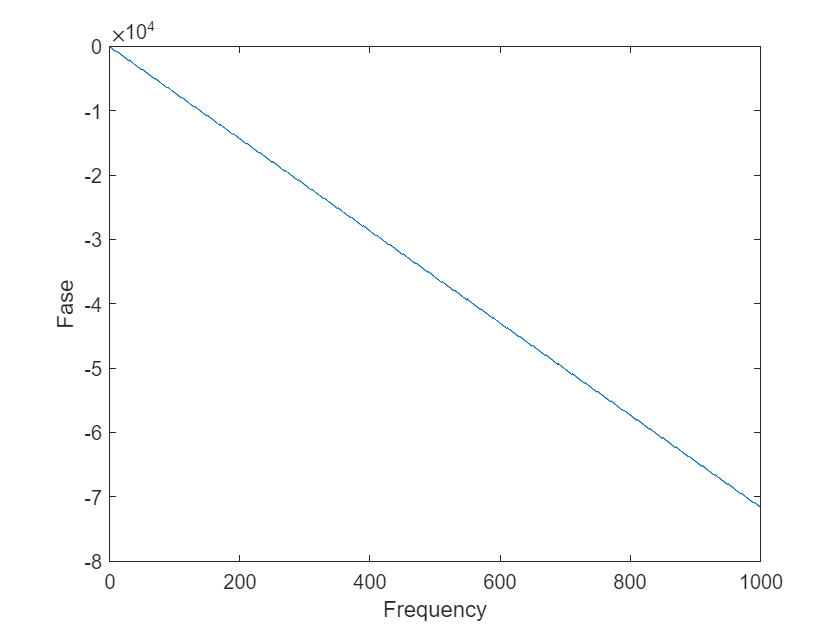

plot(f,p);
 ylabel('Fase')
xlabel('Frequency')

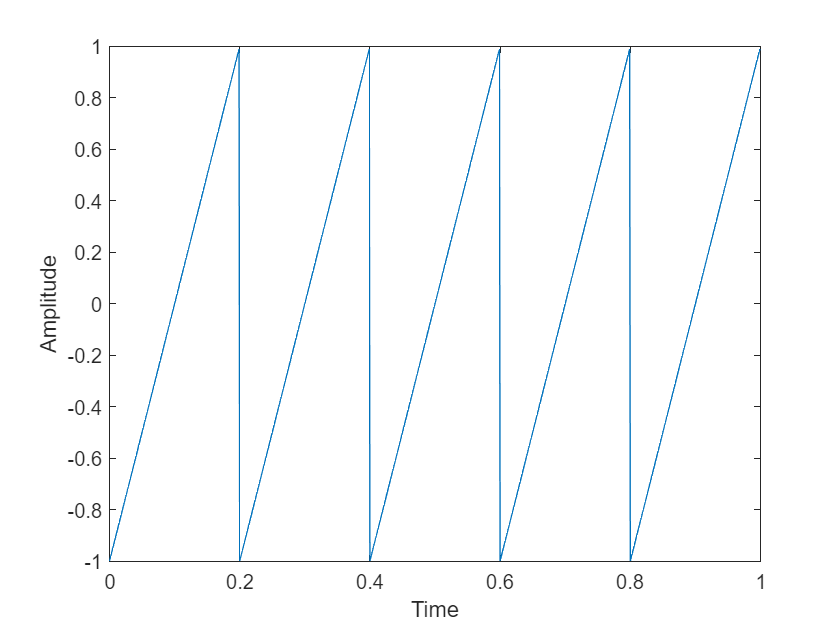

x5=sawtooth(2*pi*5*t);
plot(t,x5);
ylabel('Amplitude')
xlabel('Time')

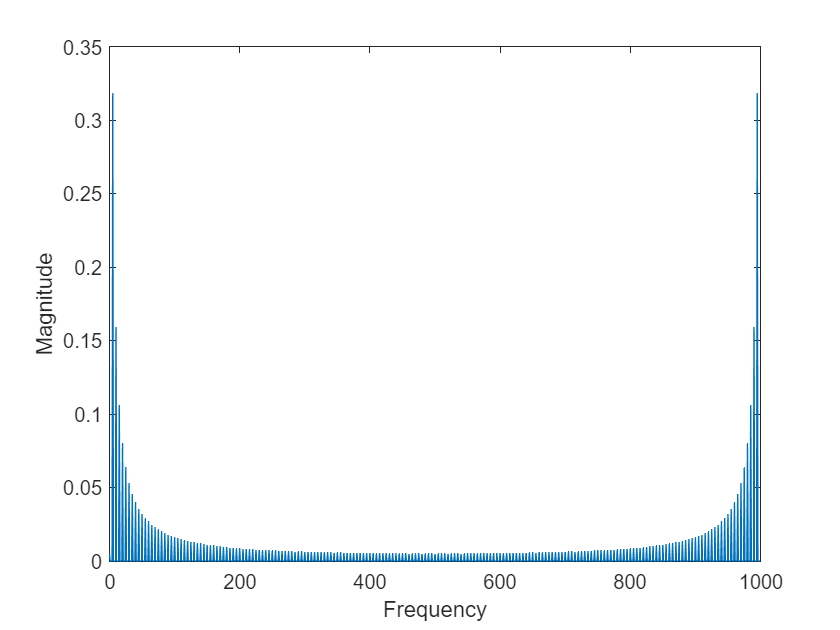

x5=fft(x5);
m=abs(x5)/N;
p=rad2deg(unwrap(angle(x5)));
plot(f,m);
ylabel('Magnitude')
xlabel('Frequency')

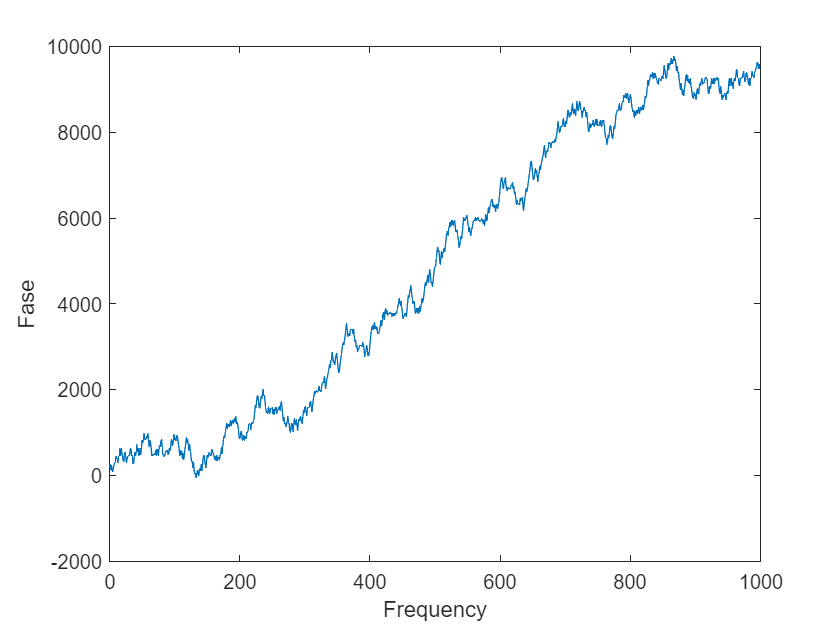

plot(f,p);
 ylabel('Fase')
xlabel('Frequency')

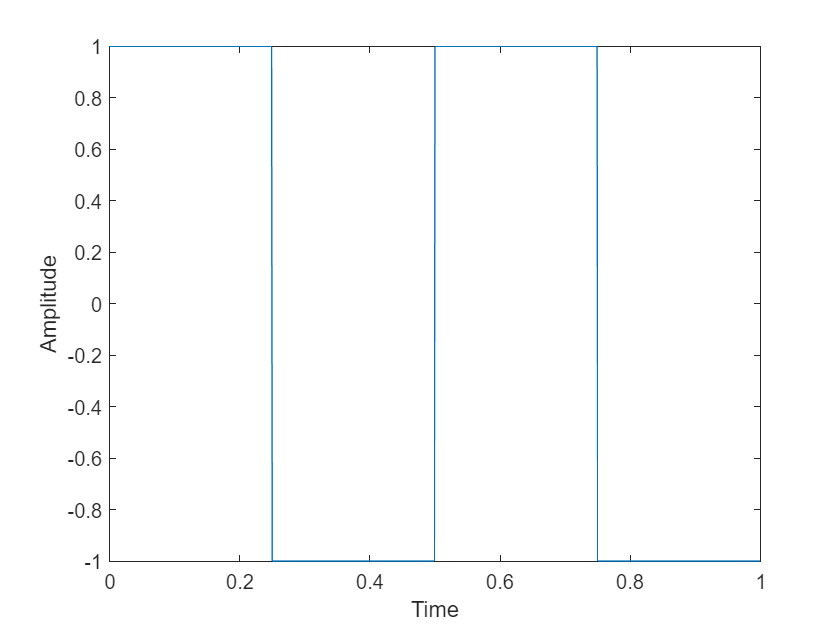

x6=square(2*pi*2*t);
plot(t,x6);
ylabel('Amplitude')
xlabel('Time')

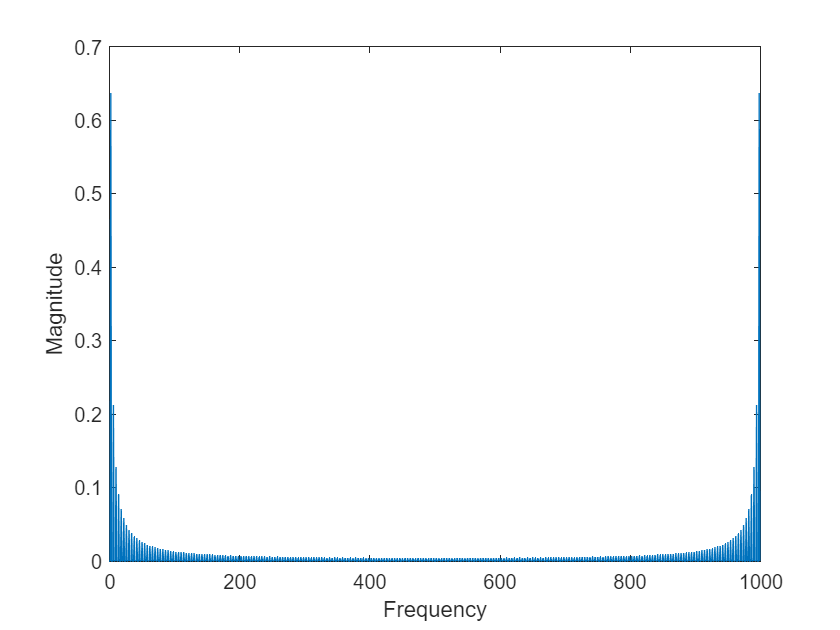

x6=fft(x6);
m=abs(x6)/N;
p=rad2deg(unwrap(angle(x6)));
plot(f,m);
ylabel('Magnitude')
xlabel('Frequency')

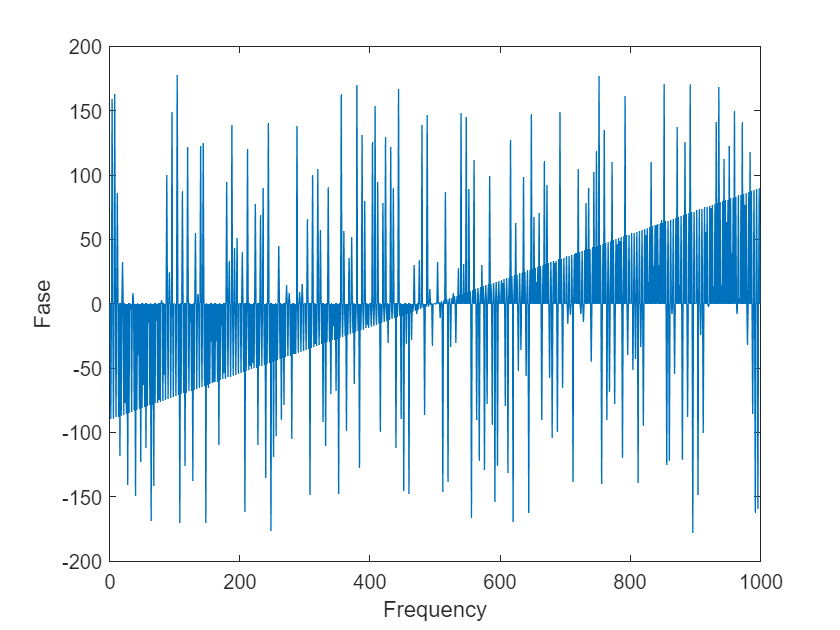

plot(f,p);
 ylabel('Fase')
xlabel('Frequency')

## 6)

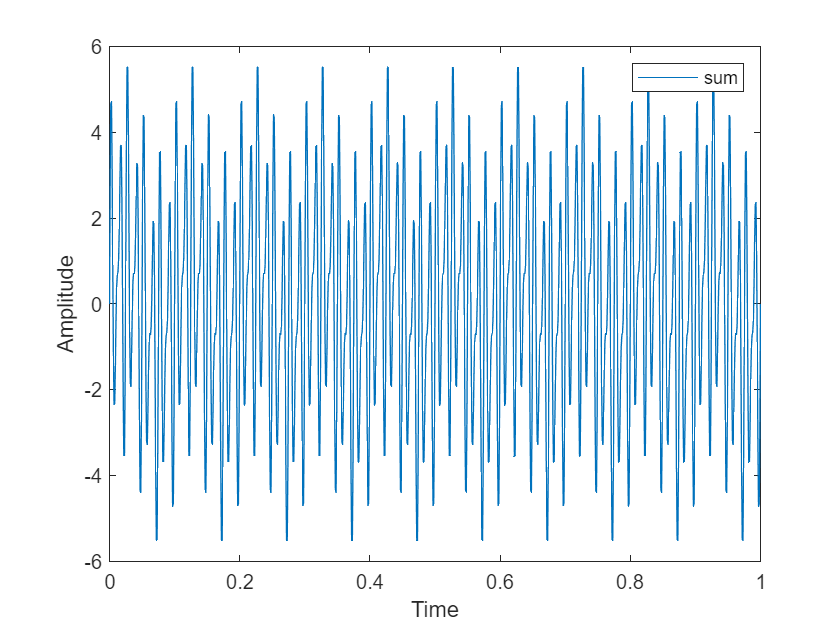

clear

N=1001;
fs=1000;
fn=fs/2; %nyquist frequency
t=1/fs*(0:(N-1));
f=fs/N*(0:(N-1));

f1=10; 
T1=1/f1;
amp1=1; 
f2=80; 
T2=1/f2; 
amp2=3; 
f3=120;
T3=1/f3;
amp3=2;

signal1=amp1*sin(2*pi*t/T1);
signal2=amp2*sin(2*pi*t/T2);
signal3=amp3*sin(2*pi*t/T3);
signal=signal1+signal2+signal3;

plot(t, signal);
ylabel('Amplitude')
xlabel('Time')
legend('sum')

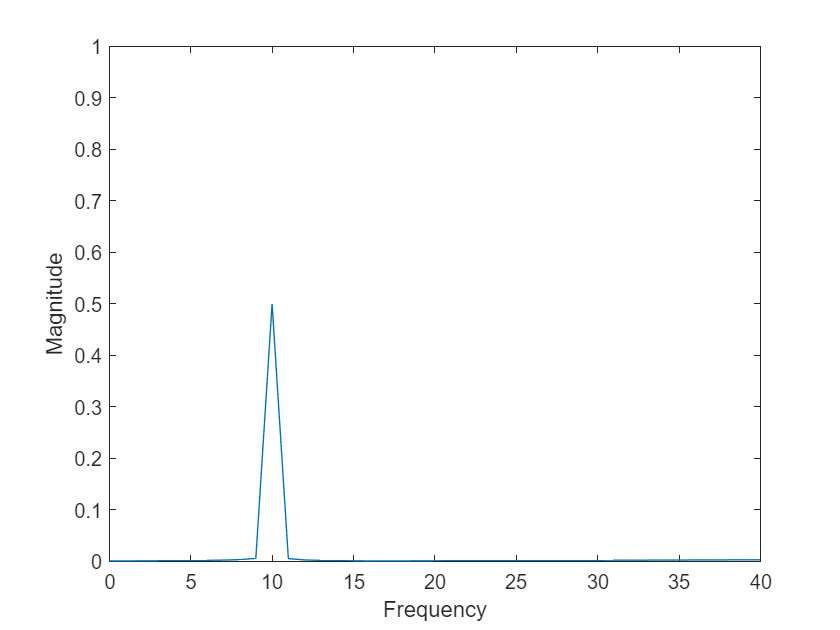


y=fft(signal);
m=abs(y)/N;
p= rad2deg(unwrap(angle(y)));

plot(f,m)
xlim([0 40])
ylim([0 1])
ylabel('Magnitude')
xlabel('Frequency')


y=ifft(y)

y =     0.0000    2.8771    4.6544    4.7225    3.2138    0.8968   -1.2205   -2.3673   -2.3272   -1.4475   -0.3633    0.3934    0.6747    0.7388    1.0145    1.7601    2.8277    3.6852    3.6979    2.5184    0.3633   -1.9966   -3.5528   -3.5369   -1.8163    1.0000    3.8124    5.5212    5.5174    3.9337    1.5388   -0.6588   -1.8882   -1.9326   -1.1390   -0.1420    0.5265    0.7191    0.6944    0.8814    1.5388    2.5192    3.2907    3.2188    1.9567   -0.2788   -2.7165   -4.3477   -4.4037   -2.7516


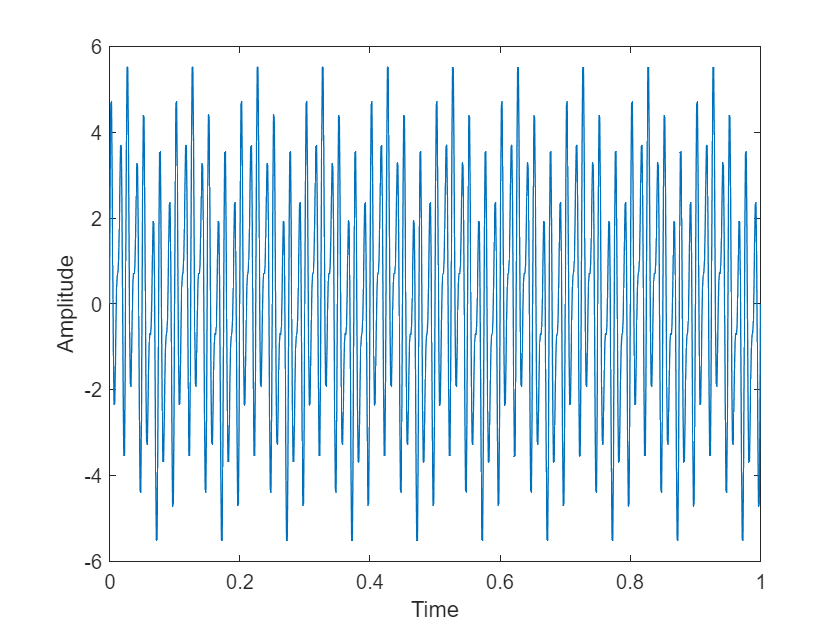

plot(t,y)
ylabel('Amplitude')
xlabel('Time')

## 7)

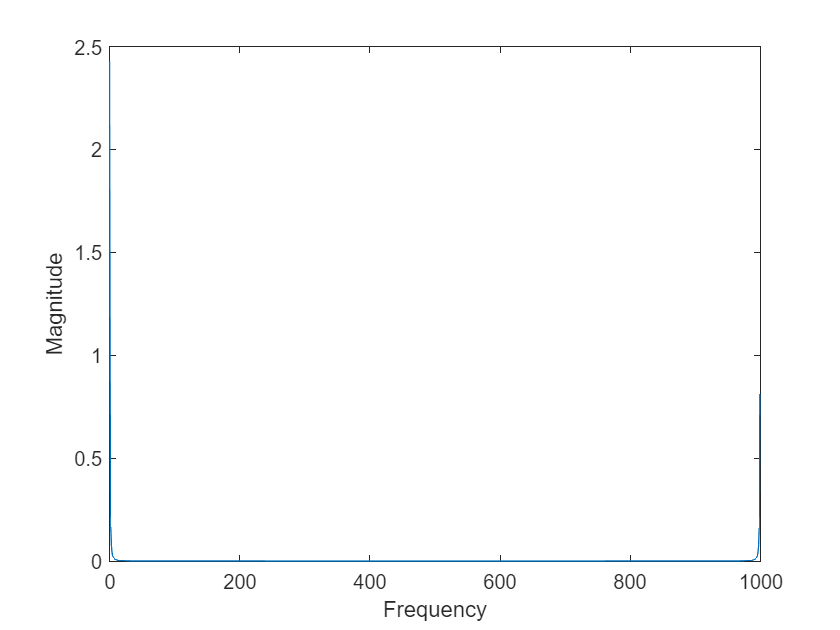

clear

N=1001;
fs=1000;
t=1/fs*(0:(N-1));
f=fs/N*(0:(N-1));
A=3; 
T=2; 
w=(2*pi)/T; 
x=((4*A)/(1*pi))*sin(1*w*t); 

y=fft(x);
m=abs(y)/N;
p= rad2deg(unwrap(angle(y)));

plot(f,m)
ylabel('Magnitude')
xlabel('Frequency')

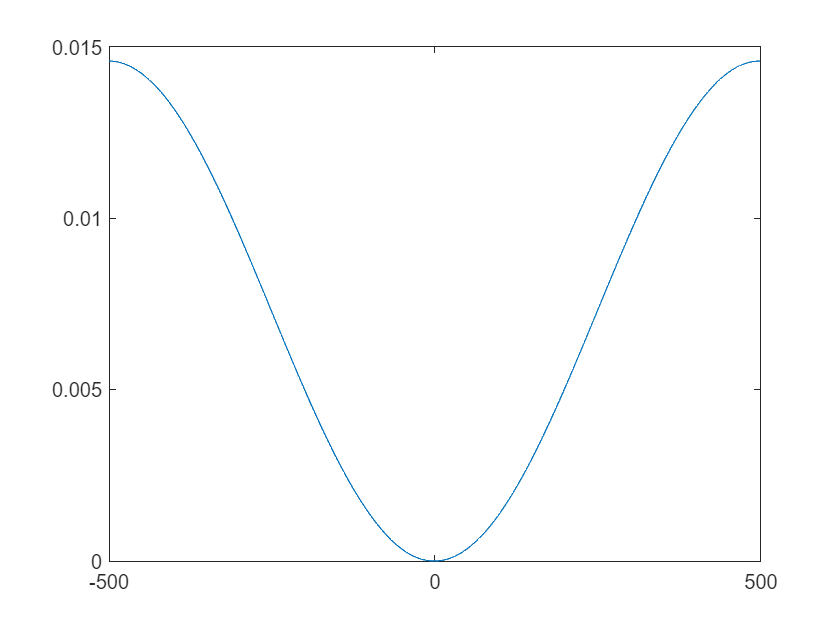

z = fftshift(x);
fshift = (-N/2:N/2-1)*(fs/N); 
powershift = abs(z).^2/N;     

plot(fshift,powershift)